states_0 = state_vec_to_struct(zeros(30, 1))

states_0 = struct with fields:
     posn_body: [3×1 double]
      vel_body: [3×1 double]
     quat_body: [1×1 quaternion]
        bias_f: [3×1 double]
    bias_omega: [3×1 double]
       posn_bv: [3×1 double]
       quat_vb: [1×1 quaternion]
      posn_tag: [3×1 double]
      quat_tag: [1×1 quaternion]


states_0.posn_body = [1, 0, 0]';
states_0.vel_body = [0, 1, 0]';
states_0.quat_body = quaternion([0, 0, 45], 'eulerd', 'xyz', 'frame');

states_0.quat_vb = quaternion([1, 0, 0, 0]);

states_0.quat_tag = quaternion([1, 0, 0, 0]);

v_states_0 = state_struct_to_vec(states_0);

f = [0, 0, 0];
omega = [0.4, 0, 0.2];

u = [f(:); omega(:)];

iterations = 16;
mat_u = repelem(u, 1, iterations);
mat_u(3, 1:2) = 1;
mat_u(3, 4:7) = -1;
mat_u(4:6, 8:end) = repelem([0; 0; 0], 1, iterations - 8 + 1);
mat_u(1:3, 10:13) = repelem([1/sqrt(2); 1/sqrt(2); 0], 1, 4);

dt = 1.5; % seconds

disp(mat_u);

  Columns 1 through 12

         0         0         0         0         0         0         0         0         0    0.7071    0.7071    0.7071
         0         0         0         0         0         0         0         0         0    0.7071    0.7071    0.7071
    1.0000    1.0000         0   -1.0000   -1.0000   -1.0000   -1.0000         0         0         0         0         0
    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000         0         0         0         0         0

  Columns 13 through 16

    0.7071         0         0         0
    0.7071         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         

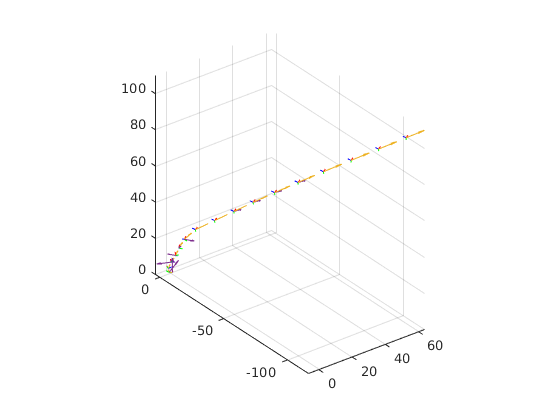

[t_out, structs_states, states_out] = sim_state_transition(v_states_0, mat_u, dt);
viz_state_transition(structs_states, mat_u);